%案例一
syms u(t) v(t)
ode1 = diff(u) == 3*u + 4*v;
ode2 = diff(v) == -4*u + 3*v;
odes = [ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}u\left(t\right)=3\,u\left(t\right)+4\,v\left(t\right)\\ \frac{\partial }{\partial t}v\left(t\right)=3\,v\left(t\right)-4\,u\left(t\right) \end{array}\right)$$

%[uSol(t), vSol(t)] = dsolve(odes)
cond1 = u(0) == 0;
cond2 = v(0) == 1;
conds = [cond1; cond2];
[uSol(t), vSol(t)] = dsolve(odes,conds)

$$uSol(t) = \sin\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

$$vSol(t) = \cos\left(4\,t\right)\,{\mathrm{e}}^{3\,t}$$

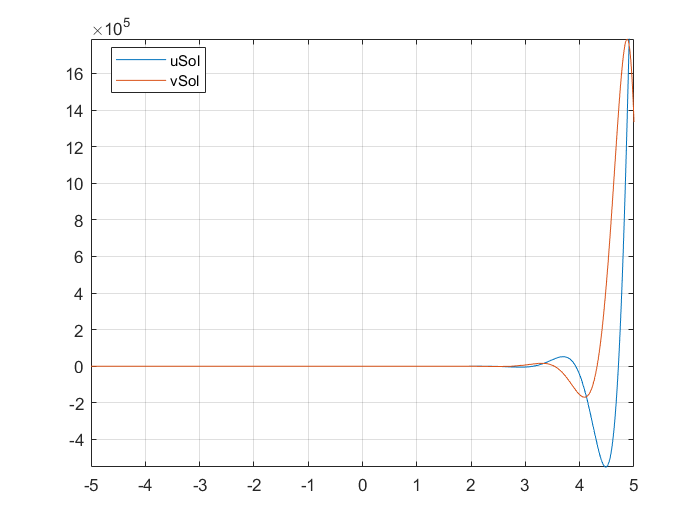

fplot(uSol)
hold on
fplot(vSol)
grid on
legend('uSol','vSol','Location','best')

%矩阵微分
clear all
clc
syms x(t) y(t)
A = [1 2; -1 1];
B = [1; t];
Y = [x; y];
odes = diff(Y) == A*Y + B

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=x\left(t\right)+2\,y\left(t\right)+1\\ \frac{\partial }{\partial t}y\left(t\right)=t-x\left(t\right)+y\left(t\right) \end{array}\right)$$

[xSol(t), ySol(t)] = dsolve(odes);
xSol(t) = simplify(xSol(t))

$$xSol(t) = \frac{2\,t}{3}+\sqrt{2}\,C_{2}\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)+\sqrt{2}\,C_{1}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)+\frac{1}{9}$$

ySol(t) = simplify(ySol(t))

$$ySol(t) = C_{1}\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)-\frac{t}{3}-C_{2}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)-\frac{2}{9}$$

C = Y(0) == [2; -1];
[xSol(t), ySol(t)] = dsolve(odes,C)

$$xSol(t) = \frac{2\,t}{3}+\frac{17\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)}{9}-\frac{7\,\sqrt{2}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)}{9}+\frac{1}{9}$$

$$ySol(t) = -\frac{t}{3}-\frac{7\,{\mathrm{e}}^{t}\,\cos\left(\sqrt{2}\,t\right)}{9}-\frac{17\,\sqrt{2}\,{\mathrm{e}}^{t}\,\sin\left(\sqrt{2}\,t\right)}{18}-\frac{2}{9}$$

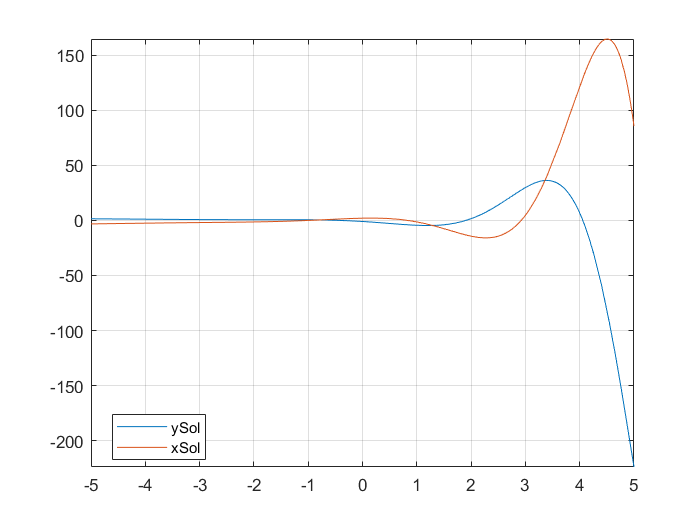

clf
fplot(ySol)
hold on
fplot(xSol)
grid on
legend('ySol','xSol','Location','best')